P = mod(56, 4) + 4

P = 4

Q = mod(11,4)

Q = 3

R = mod(2022+56, 3)

R = 2

S = mod(56, 3)

S = 2


n = 0:5;

x = zeros(1,6);
for k = 1:length(n)
    if n(k) < 2
        x(k) = sin(n(k)) + 2*cos(2*n(k)) + 2;
    elseif n(k) < 4
        x(k) = 2^n(k);
    end
end

y = zeros(1,6);
for k = 1:length(n)
    if n(k) < 2
        y(k) = (-1)^n(k) + mod(n(k),2);
    elseif n(k) < 4
        y(k) = n(k) - 2;
    end
end


## ZADATAK 1, a)

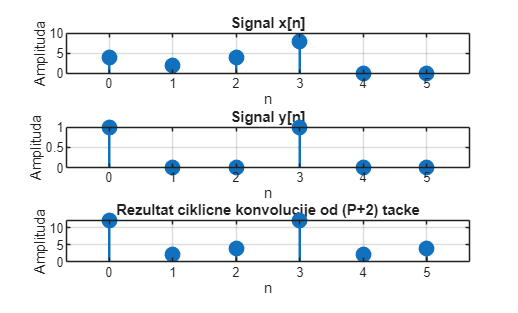



conv_result = zeros(1,6);
for m = 0:5
    sum_val = 0;
    for k = 0:5
        index = mod(m - k, 6);
        sum_val = sum_val + x(k+1) * y(index+1);
    end
    conv_result(m+1) = sum_val;
end

figure;

subplot(3,1,1);
stem(n, x, 'filled', 'LineWidth', 1.5, 'MarkerSize', 8);
title('Signal x[n]');
xlabel('n');
ylabel('Amplituda');
grid on;

subplot(3,1,2);
stem(n, y, 'filled', 'LineWidth', 1.5, 'MarkerSize', 8);
title('Signal y[n]');
xlabel('n');
ylabel('Amplituda');
grid on;

subplot(3,1,3);
stem(n, conv_result, 'filled', 'LineWidth', 1.5, 'MarkerSize', 8);
title('Rezultat ciklicne konvolucije od (P+2) tacke');
xlabel('n');
ylabel('Amplituda');
grid on;

## ZADATAK 1, b)

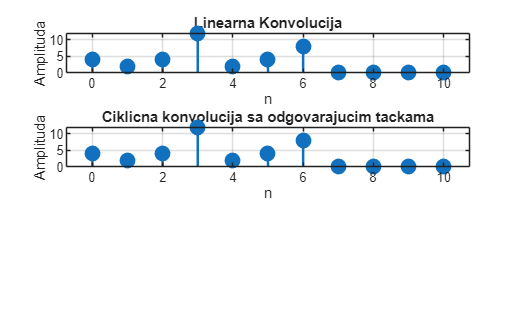

N = length(x);
M = length(y);

linear_conv = zeros(1, N+M-1);

for m = 0:N+M-2
    sum_val = 0;
    for k = max(0, m-(M-1)):min(m, N-1)
          sum_val = sum_val + x(k+1) * y(m-k+1);
    end
    linear_conv(m+1) = sum_val;
end

x_sredjeno = [x zeros(1, M-1)];
y_sredjeno= [y zeros(1, N-1)];

ciklicna_conv = zeros(1, N+M-1);
for m = 0:N+M-2
    sum_val = 0;
    for k = 0:N+M-2
        index = mod(m - k, N + M - 1);
        sum_val = sum_val + x_sredjeno(k+1) * y_sredjeno(index+1);
    end
    ciklicna_conv(m+1) = sum_val;
end

figure;

subplot(3,1,1);
stem(0:length(linear_conv)-1, linear_conv, 'filled', 'LineWidth', 1.5, 'MarkerSize', 8);
title('Linearna Konvolucija');
xlabel('n');
ylabel('Amplituda');
grid on;

subplot(3,1,2);
stem(0:length(ciklicna_conv)-1, ciklicna_conv, 'filled', 'LineWidth', 1.5, 'MarkerSize', 8);
title('Ciklicna konvolucija sa odgovarajucim tackama');
xlabel('n');
ylabel('Amplituda');
grid on;

## ZADATAK 2